# *Lab.2 Analisis Circuitos RLC *

clc
clear
close all

%Voltaje en el inductor a 900kHz
datos = readmatrix("NewFile5.csv");
tiempo = datos(:, 1);
tension = datos(:, 2);


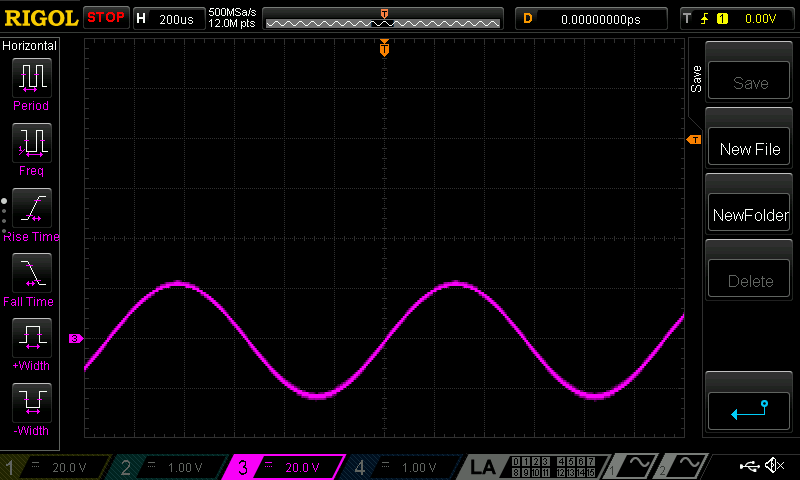



%Voltaje en de entrada a 900kHz
datos = readmatrix("NewFile6.csv");
tiempo = datos(:, 1);
tension = datos(:, 2);


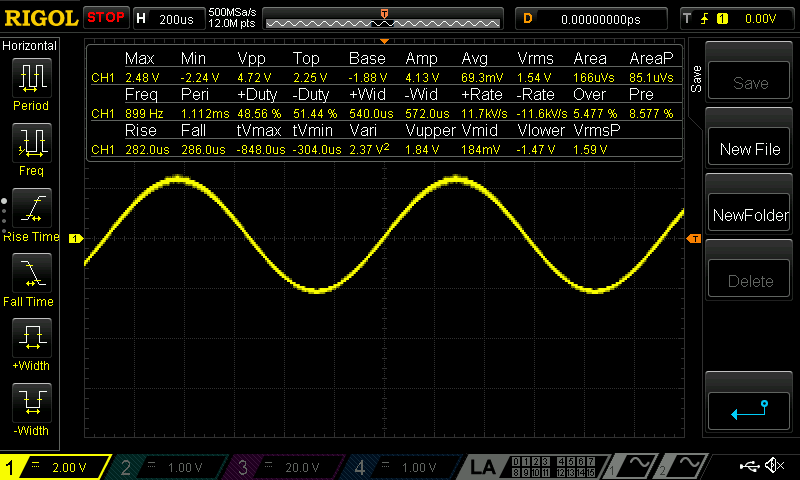


%Voltaje en el inductor pero en zona resitiva 1.41MHz
datos = readmatrix("NewFile4.csv");
tiempo = datos(:, 1);
tension = datos(:, 2);


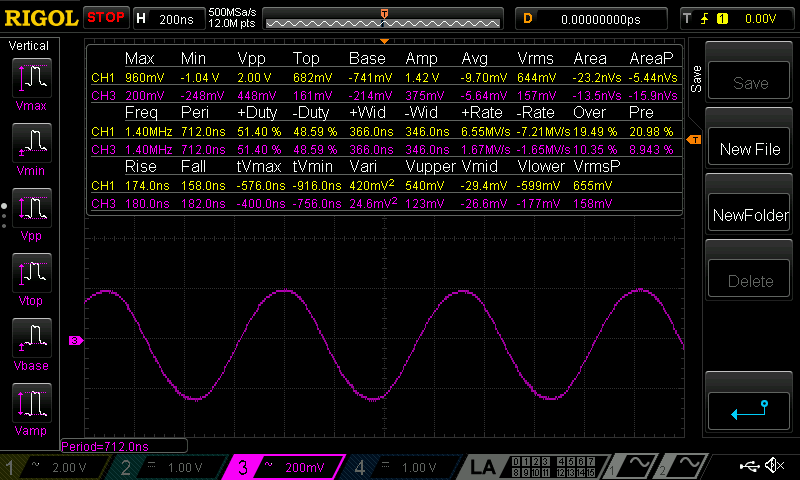


t = 12*200e-6;
ti= 12e06/t; %velocidad de muestreo
in = 1/ti;
tiempo_muestreo = tiempo*in;

plot(tiempo_muestreo, tension);
xlabel('Tiempo en ms');
ylabel('Tensión en el inductor');
ylim([-50 50]);


Vs=10

Vs = 10

R=1e03

R = 1000

C=100e-9

C = 1.0000e-07

L=12.5e-03

L = 0.0125

% Simulation parameters
f=30000

f = 30000

T = 1/f

T = 3.3333e-05

Vs_p = Vs*sqrt(2);
Tsim = 3*T

Tsim = 1.0000e-04

% TolRel = 1e-4;
SampligTime = 200e-9;

w=2*pi*f;
Xl=w*L*1i;
Xc=1/(w*C*1i);

Is=Vs/(R+Xl+Xc)

Is = 0.0016 - 0.0037i

abs(Is)

ans = 0.0040

angle(Is)*180/pi

ans = -66.5300

ILinitial = sqrt(2) * abs(Is) * sin(angle(Is))

ILinitial = -0.0052

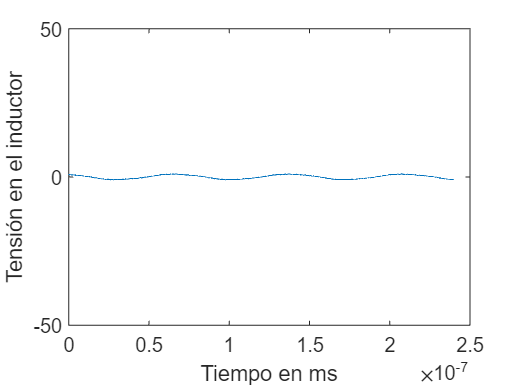

sim("DiscreteCircuit.slx")


% Simulation Data
Time = Data{1}.Values.Time;
I_L = Data{1}.Values.Data;
V_L = Data{2}.Values.Data;
V_s = Data{3}.Values.Data;

tiledlayout(2,1)

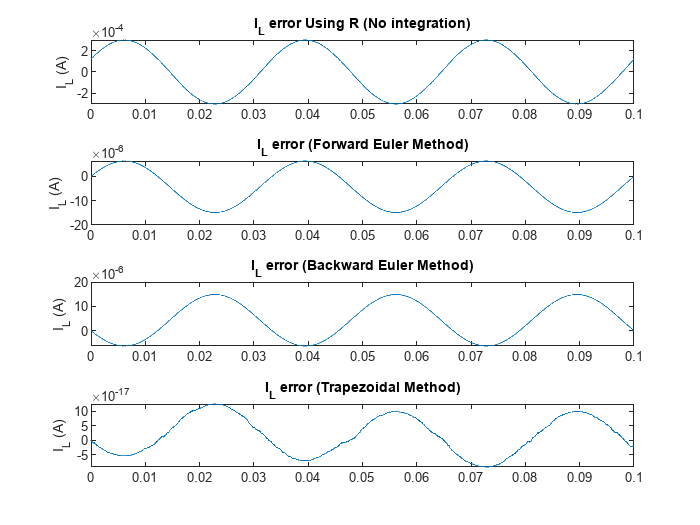

nexttile
yyaxis left
plot(Time*1e3,V_s);
ylabel('Voltage (V)')
yyaxis right
plot(Time*1e3,I_L)
ylabel('Current (A)')
grid on

nexttile
plot(Time*1e3,V_L);
ylabel('Voltage (V)')
xlabel('Time (ms)')
grid on

SamplingRate = SampligTime; % Simulation parameter

DiscreteIntegratorSolution = zeros(length(V_L),3);
% Initialize the first value of the solution
DiscreteIntegratorSolution(1,:) = ILinitial*[1 1 1];        

k = 1/L; % Proportional integration
% Integrate using three methods
for i = 2:length(V_L)
    DiscreteIntegratorSolution(i,2) = DiscreteIntegratorSolution(i-1,2) + k * SamplingRate * V_L(i); % Backward Euler implementation
    DiscreteIntegratorSolution(i,3) = DiscreteIntegratorSolution(i-1,3) + k * SamplingRate * (V_L(i) + V_L(i-1))/2 ; % Trapezoidal implementation
    DiscreteIntegratorSolution(i,1) = DiscreteIntegratorSolution(i-1,1) + k * SamplingRate * V_L(i-1); % Backward Euler implementation
end
I_R = (V_s - V_L)/R;        % I_L Using resistor
error_method1 = I_L - I_R;  % Error

% I_L Error Using the three integration methods
error_method2 = I_L - DiscreteIntegratorSolution(:,1);  % Error forward
error_method3 = I_L - DiscreteIntegratorSolution(:,2);  % Error backward
error_method4 = I_L - DiscreteIntegratorSolution(:,3);  % Error trapezoidal
% Error plots
figure
tiledlayout(4,1)
nexttile
plot(Time*1e3, error_method1)
ylabel('I_L (A)')
title('I_L error Using R (No integration)')
nexttile
plot(Time*1e3, error_method2)
ylabel('I_L (A)')
title('I_L error (Forward Euler Method)')
nexttile
plot(Time*1e3, error_method3)
ylabel('I_L (A)')
title('I_L error (Backward Euler Method)')
nexttile
plot(Time*1e3, error_method4)
ylabel('I_L (A)')
title('I_L error (Trapezoidal Method)')


Vl1=Xl*Is

Vl1 = 8.6076 + 3.7373i

Vc1=Xc*Is

Vc1 = -0.1938 - 0.0841i